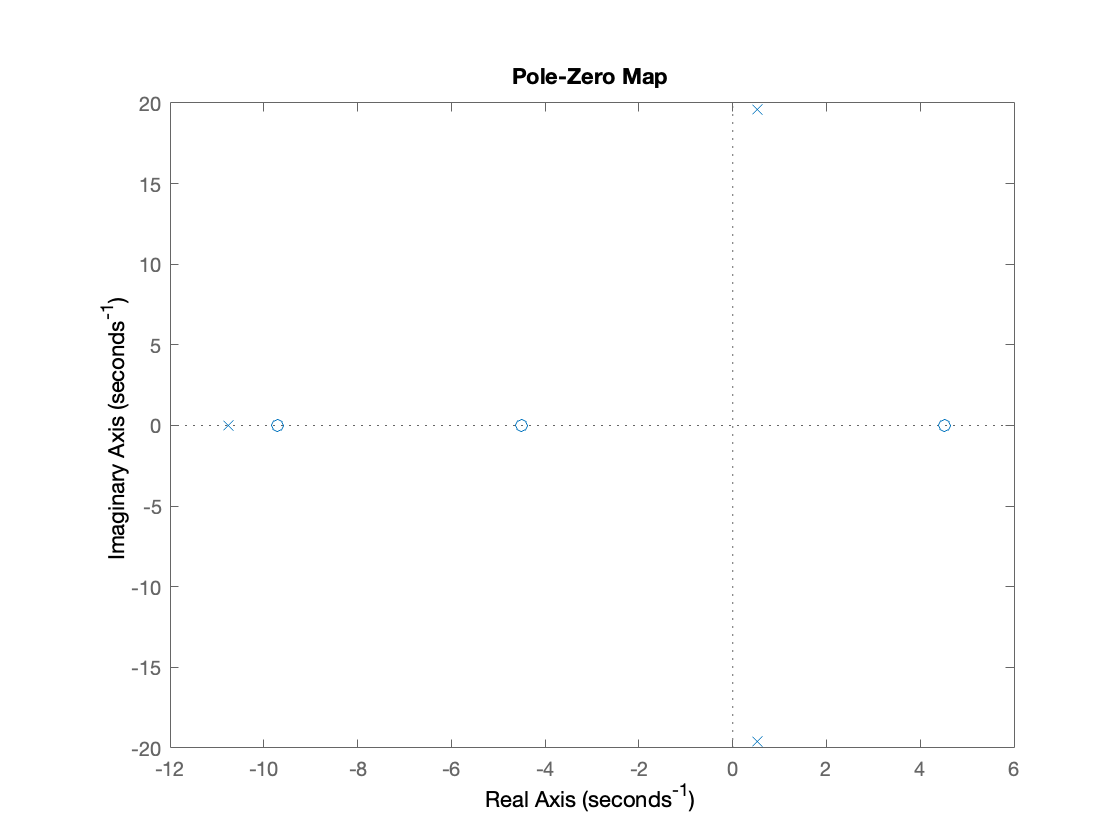

syms s  Kp Ki l g tau k x

tau_value = 0.103;
k_value = 2.439;
l_value = 0.4822;
g_value = 9.8;
kp_value = 8;
ki_value = 88;

Ms = (k/tau) / (s+(1/tau));
Hs = (-s/l) / (s^2-(g/l));
Ks = Kp + (Ki/s);

transfer_function = ((simplify((1)/(1 - (Hs*Ks*Ms)))));

hello = subs(transfer_function, l, l_value);
hello = subs(hello, k, k_value);
hello = subs(hello, g, g_value);
hello = subs(hello, tau, tau_value);
hello = subs(hello, Kp, kp_value);
hello = subs(hello, Ki, ki_value);

[N, D] = numden(hello);

transfer_matlab_form = tf(sym2poly(N), sym2poly(D));
pzplot(transfer_matlab_form)